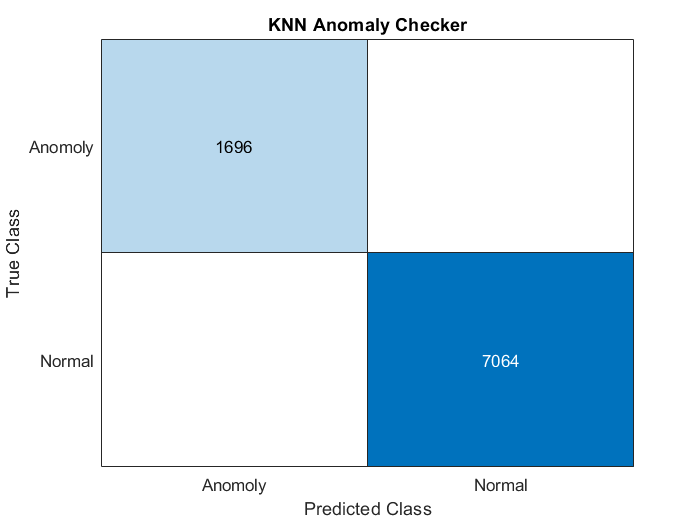

load("Dataset2.mat");
ML_KNN = trainClassifierKNN(CAF031033401_Train);
ML_SVM = trainClassifierSVM(CAF031033401_Train);
ML_NB = trainClassifierNB(CAF031033401_Train);
figure;
confusionchart(ML_KNN.predictFcn(CAF031033401_Test),CAF031033401_Test.Class, ...
    'Title','KNN Anomaly Checker');

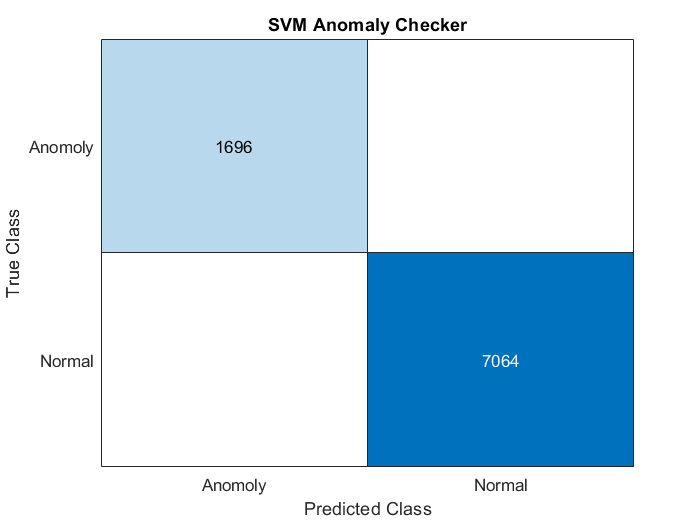

confusionchart(smartAgri_SVM.predictFcn(CAF031033401_Test),CAF031033401_Test.Class, ...
    'Title','SVM Anomaly Checker');

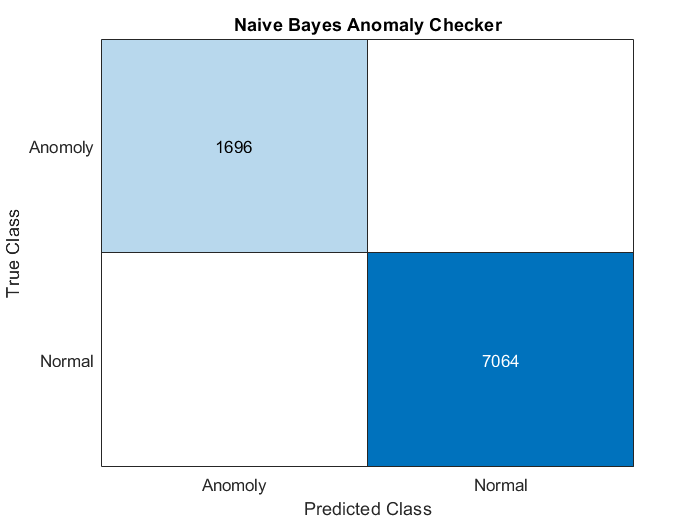

confusionchart(smartAgri_NB.predictFcn(CAF031033401_Test),CAF031033401_Test.Class, ...
    'Title','Naive Bayes Anomaly Checker');

function [trainedClassifier, validationAccuracy] = trainClassifierKNN(trainingData)
% [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% returns a trained classifier and its accuracy. This code recreates the
% classification model trained in Classification Learner app. Use the
% generated code to automate training the same model with new data, or to
% learn how to programmatically train models.
%
%  Input:
%      trainingData: a table containing the same predictor and response
%       columns as imported into the app.
%
%  Output:
%      trainedClassifier: a struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: a function to make predictions on new
%       data.
%
%      validationAccuracy: a double containing the accuracy in percent. In
%       the app, the History list displays this overall accuracy score for
%       each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 05-Apr-2021 05:00:59


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'CAF031_VW_30cm', 'CAF031_T_30cm', 'CAF033_VW_30cm', 'CAF033_T_30cm', 'CAF401_VW_30cm', 'CAF401_T_30cm'};
predictors = inputTable(:, predictorNames);
response = inputTable.Class;
isCategoricalPredictor = [false, false, false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationKNN = fitcknn(...
    predictors, ...
    response, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 1, ...
    'DistanceWeight', 'Equal', ...
    'Standardize', true, ...
    'ClassNames', categorical({'Anomoly'; 'Normal'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
knnPredictFcn = @(x) predict(classificationKNN, x);
trainedClassifier.predictFcn = @(x) knnPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'CAF031_T_30cm', 'CAF031_VW_30cm', 'CAF033_T_30cm', 'CAF033_VW_30cm', 'CAF401_T_30cm', 'CAF401_VW_30cm'};
trainedClassifier.ClassificationKNN = classificationKNN;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2019b.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'CAF031_VW_30cm', 'CAF031_T_30cm', 'CAF033_VW_30cm', 'CAF033_T_30cm', 'CAF401_VW_30cm', 'CAF401_T_30cm'};
predictors = inputTable(:, predictorNames);
response = inputTable.Class;
isCategoricalPredictor = [false, false, false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationKNN, 'KFold', 10);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
end


function [trainedClassifier, validationAccuracy] = trainClassifierSVM(trainingData)
% [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% returns a trained classifier and its accuracy. This code recreates the
% classification model trained in Classification Learner app. Use the
% generated code to automate training the same model with new data, or to
% learn how to programmatically train models.
%
%  Input:
%      trainingData: a table containing the same predictor and response
%       columns as imported into the app.
%
%  Output:
%      trainedClassifier: a struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: a function to make predictions on new
%       data.
%
%      validationAccuracy: a double containing the accuracy in percent. In
%       the app, the History list displays this overall accuracy score for
%       each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 05-Apr-2021 05:10:06


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'CAF031_VW_30cm', 'CAF031_T_30cm', 'CAF033_VW_30cm', 'CAF033_T_30cm', 'CAF401_VW_30cm', 'CAF401_T_30cm'};
predictors = inputTable(:, predictorNames);
response = inputTable.Class;
isCategoricalPredictor = [false, false, false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.
classificationSVM = fitcsvm(...
    predictors, ...
    response, ...
    'KernelFunction', 'gaussian', ...
    'PolynomialOrder', [], ...
    'KernelScale', 0.61, ...
    'BoxConstraint', 1, ...
    'Standardize', true, ...
    'ClassNames', categorical({'Anomoly'; 'Normal'}));

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
svmPredictFcn = @(x) predict(classificationSVM, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'CAF031_T_30cm', 'CAF031_VW_30cm', 'CAF033_T_30cm', 'CAF033_VW_30cm', 'CAF401_T_30cm', 'CAF401_VW_30cm'};
trainedClassifier.ClassificationSVM = classificationSVM;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2019b.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'CAF031_VW_30cm', 'CAF031_T_30cm', 'CAF033_VW_30cm', 'CAF033_T_30cm', 'CAF401_VW_30cm', 'CAF401_T_30cm'};
predictors = inputTable(:, predictorNames);
response = inputTable.Class;
isCategoricalPredictor = [false, false, false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationSVM, 'KFold', 10);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
end


function [trainedClassifier, validationAccuracy] = trainClassifierNB(trainingData)
% [trainedClassifier, validationAccuracy] = trainClassifier(trainingData)
% returns a trained classifier and its accuracy. This code recreates the
% classification model trained in Classification Learner app. Use the
% generated code to automate training the same model with new data, or to
% learn how to programmatically train models.
%
%  Input:
%      trainingData: a table containing the same predictor and response
%       columns as imported into the app.
%
%  Output:
%      trainedClassifier: a struct containing the trained classifier. The
%       struct contains various fields with information about the trained
%       classifier.
%
%      trainedClassifier.predictFcn: a function to make predictions on new
%       data.
%
%      validationAccuracy: a double containing the accuracy in percent. In
%       the app, the History list displays this overall accuracy score for
%       each model.
%
% Use the code to train the model with new data. To retrain your
% classifier, call the function from the command line with your original
% data or new data as the input argument trainingData.
%
% For example, to retrain a classifier trained with the original data set
% T, enter:
%   [trainedClassifier, validationAccuracy] = trainClassifier(T)
%
% To make predictions with the returned 'trainedClassifier' on new data T2,
% use
%   yfit = trainedClassifier.predictFcn(T2)
%
% T2 must be a table containing at least the same predictor columns as used
% during training. For details, enter:
%   trainedClassifier.HowToPredict

% Auto-generated by MATLAB on 05-Apr-2021 05:11:25


% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'CAF031_VW_30cm', 'CAF031_T_30cm', 'CAF033_VW_30cm', 'CAF033_T_30cm', 'CAF401_VW_30cm', 'CAF401_T_30cm'};
predictors = inputTable(:, predictorNames);
response = inputTable.Class;
isCategoricalPredictor = [false, false, false, false, false, false];

% Train a classifier
% This code specifies all the classifier options and trains the classifier.

% Expand the Distribution Names per predictor
% Numerical predictors are assigned either Gaussian or Kernel distribution and categorical predictors are assigned mvmn distribution
% Gaussian is replaced with Normal when passing to the fitcnb function
distributionNames =  repmat({'Normal'}, 1, length(isCategoricalPredictor));
distributionNames(isCategoricalPredictor) = {'mvmn'};

if any(strcmp(distributionNames,'Kernel'))
    classificationNaiveBayes = fitcnb(...
        predictors, ...
        response, ...
        'Kernel', 'Normal', ...
        'Support', 'Unbounded', ...
        'DistributionNames', distributionNames, ...
        'ClassNames', categorical({'Anomoly'; 'Normal'}));
else
    classificationNaiveBayes = fitcnb(...
        predictors, ...
        response, ...
        'DistributionNames', distributionNames, ...
        'ClassNames', categorical({'Anomoly'; 'Normal'}));
end

% Create the result struct with predict function
predictorExtractionFcn = @(t) t(:, predictorNames);
naiveBayesPredictFcn = @(x) predict(classificationNaiveBayes, x);
trainedClassifier.predictFcn = @(x) naiveBayesPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.RequiredVariables = {'CAF031_T_30cm', 'CAF031_VW_30cm', 'CAF033_T_30cm', 'CAF033_VW_30cm', 'CAF401_T_30cm', 'CAF401_VW_30cm'};
trainedClassifier.ClassificationNaiveBayes = classificationNaiveBayes;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2019b.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new table, T, use: \n  yfit = c.predictFcn(T) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nThe table, T, must contain the variables returned by: \n  c.RequiredVariables \nVariable formats (e.g. matrix/vector, datatype) must match the original training data. \nAdditional variables are ignored. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% This code processes the data into the right shape for training the
% model.
inputTable = trainingData;
predictorNames = {'CAF031_VW_30cm', 'CAF031_T_30cm', 'CAF033_VW_30cm', 'CAF033_T_30cm', 'CAF401_VW_30cm', 'CAF401_T_30cm'};
predictors = inputTable(:, predictorNames);
response = inputTable.Class;
isCategoricalPredictor = [false, false, false, false, false, false];

% Perform cross-validation
partitionedModel = crossval(trainedClassifier.ClassificationNaiveBayes, 'KFold', 10);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
end